# Lagrange Interpolation Demo

Consider the following data for $f(x)=\cos(x)$

x=[0,pi/6,pi/4,pi/3,pi/2];
y=[1, sqrt(3)/2, sqrt(2)/2, 1/2, 0];

Approximate $\cos 5^\circ$.

t=pi/36;
v=Lagrange(x,y,t)

v = 0.9964

cos(t)

ans = 0.9962

Plot on the same graph the function and its Lagrange polynomial for the given data set

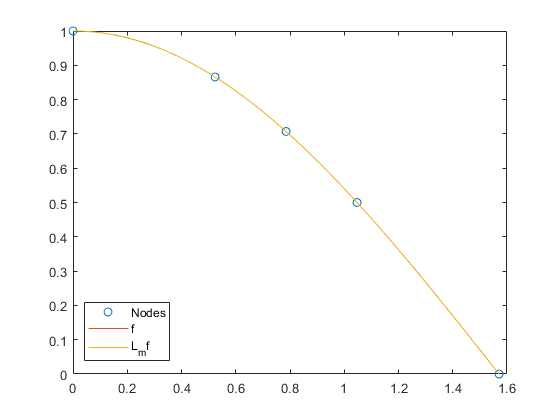

t=linspace(0,pi/2,100);
vl=Lagrange(x,y,t);
plot(x,y,'o',t,cos(t),t,vl)
legend('Nodes','f','L_mf','Location', 'best')

Plot the error $|L_4f(x)-\cos(x)|$ on $[-1,1]$.

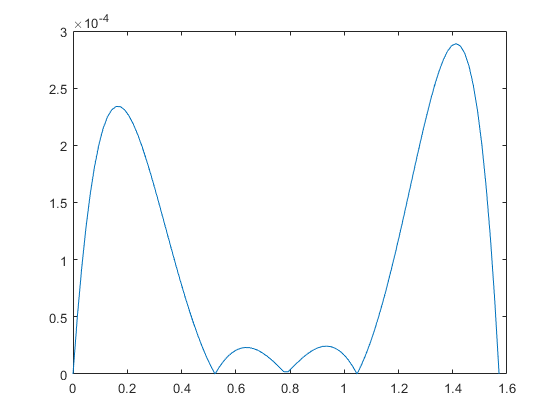

plot(t,abs(vl-cos(t)))

Here is the code for `Lagrange` function:

function fi=Lagrange(x,y,xi)
%LAGRANGE - compute Lagrange interpolation polynomial
%call fi=Lagrange(x,y,xi)
% x,y - nodes coordinates
% xi - evaluation points

if nargin ~=3
    error('Illegal number of arguments')
end
[mu,nu]=size(xi);
fi=zeros(mu,nu);
np1=length(y);
for i=1:np1
    z=ones(mu,nu);
    for j=[1:i-1,i+1:np1]
        z=z.*(xi-x(j))/(x(i)-x(j));
    end
    fi=fi+z*y(i);
end
end